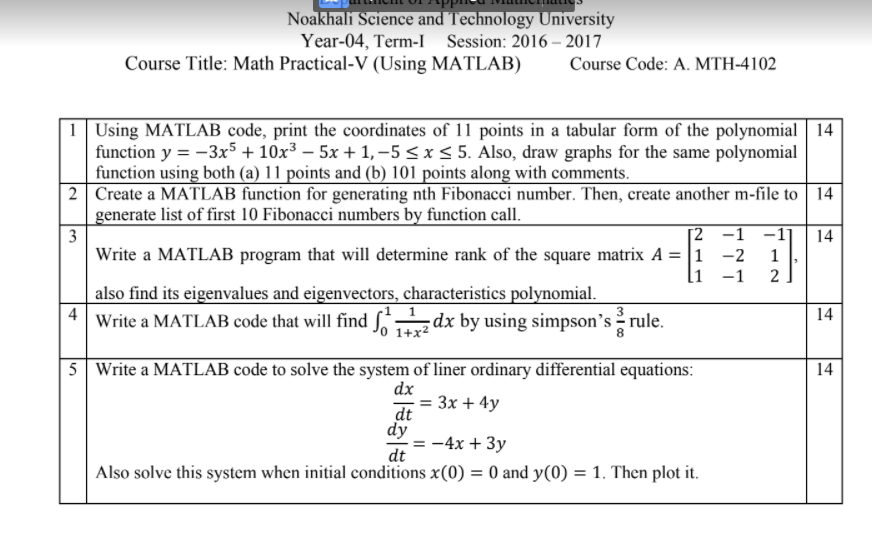

question-1:

answer:


x = linspace(-5,5,11);
y = fun1(x);
A = [x ;y];
fprintf('%6s %20s\n','x','y');

     x                    y


fprintf('%6d %22d\n',A);

    -5                   8151
    -4                   2453
    -3                    475
    -2                     27
    -1                     -1
     0                      1
     1                      3
     2                    -25
     3                   -473
     4                  -2451
     5                  -8149


question-2:

answer:

B= [0 1;1 1];
n = input('enter a number\n');
C = B^n;
fprintf("%dth fibonacci number is %d ",n,C(1,2));

10th fibonacci number is 55 

question-3:

answer:

clear all;
syms x I;
A = [2 -1 -1;1 -2 1;1 -1 2];
fprintf("rank is %d", rank(A));

rank is 3

[V D]=eig(A);
fprintf("eigen vector is")

eigen vector is

disp(V)

   0.7630 + 0.0000i   0.7630 + 0.0000i  -0.3194 + 0.0000i
   0.1595 - 0.2028i   0.1595 + 0.2028i  -0.9311 + 0.0000i
   0.0436 - 0.5911i   0.0436 + 0.5911i  -0.1764 + 0.0000i



fprintf("eigen value is")

eigen value is

disp(D)

   1.7338 + 1.0405i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   1.7338 - 1.0405i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -1.4675 + 0.0000i



eq = 0;
polA = charpoly(A);
for i=1:length(polA)
    if i==length(polA)
        eq = eq + polA(i)*I;
    else
        eq = eq + x^(length(polA)-i) * polA(i);
    end
end

disp(eq)

$$x^{3}-2\,x^{2}-x+6\,\text{I}$$

question-4:

answer:


clear all;
close all;
clc;

f=@(x) 1/(1+x^2);

a=input('Enter lower limit of integral=');
b=input('Enter upper limit of integral=');
n=input('Enter number of intervals (multiple of 3)=');

h=(b-a)/n;

sum1=0.0;
sum2=0.0;
sum3=0.0;

for i=1:3:n-2
    x=a+i*h;
    sum1=sum1+f(x);
end
for i=2:3:n-1
    x=a+i*h;
    sum2=sum2+f(x);
end
for i=3:3:n-3
    x=a+i*h;
    sum3=sum3+f(x);
end

simp=3*h*(f(a)+3.0*sum1+3.0*sum2+2.0*sum3+f(b))/8.0;

fprintf('Integrated value is %f',simp)

Integrated value is 0.784615

syms y(t) x(t) t 


eq1 = diff(y,t) == 3*x + 4*y;
eq2 = diff(x,t) == -4*x +3*y;
eqns = [eq1,eq2];
cond = [y(0)==1,x(0)==1];
sol = dsolve(eqns,cond);
fprintf("solution of x is")

solution of x is

disp(sol.x)

$$\frac{3\,{\mathrm{e}}^{-5\,t}}{5}+\frac{2\,{\mathrm{e}}^{5\,t}}{5}$$

fprintf("solution of y is")

solution of y is

disp(sol.y)

$$\frac{6\,{\mathrm{e}}^{5\,t}}{5}-\frac{{\mathrm{e}}^{-5\,t}}{5}$$

function y = fun1(x)
y = -3*x.^5 + 10*x.^3 - 5*x +1;
end